Report 2 Mikołaj Sichoń

I=(im2bw((rgb2gray(imread("Objects.png"))), 0.5));

imshow(I)
[label,~]=bwlabel(I);
feat=regionprops(label,"all");

for i=1:length(feat)
if (feat(i).BoundingBox(3)*feat(i).BoundingBox(4))==feat(i).Area
feat(i).Shape='rectangle';

we take size of bounding box and check if equals area, if yes thats a

rectangle sicne the bounding box is also a rectangle

if feat(i).BoundingBox(3)^2==feat(i).Area
feat(i).Shape='square';

since a square has all same sides we check just like in the previous case

for the relation between bounding box and area, just in this case we

square one side

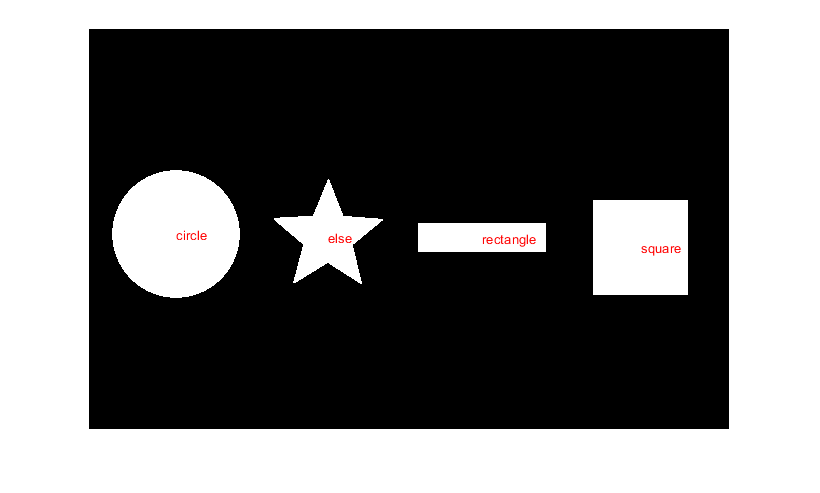

end
elseif feat(i).Circularity>=1
feat(i).Shape='circle';
else
feat(i).Shape='else';
end
text(feat(i).Centroid(1), feat(i).Centroid(2),feat(i).Shape,'Color', 'r')
end

Above code allows us to select rectnagles, squares and circles.

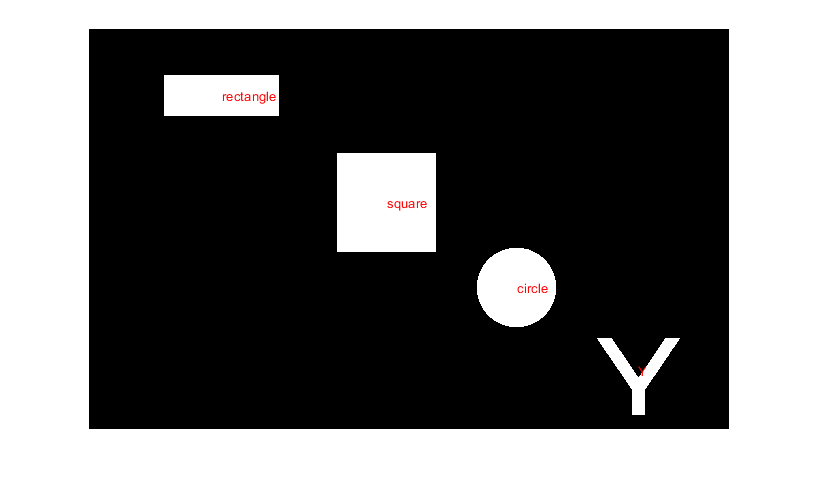

I=1-(im2bw((rgb2gray(imread("Objects2.jpg"))), 0.5));

imshow(I)
[label, num]=bwlabel(I);
feat=regionprops(label,"all");

for i=1:length(feat)
if (feat(i).BoundingBox(3)*feat(i).BoundingBox(4))==feat(i).Area
feat(i).Shape='rectangle';
if feat(i).BoundingBox(3)==feat(i).BoundingBox(4)
feat(i).Shape='square';
end
elseif feat(i).Circularity>=1
feat(i).Shape='circle';
else
feat(i).Shape='Y';
end
text(feat(i).Centroid(1), feat(i).Centroid(2),feat(i).Shape,'Color', 'r')
end

Here we have another demonstration of haw we can detect rectangles, squares and circles. By the process of elimination we also found the letter Y.

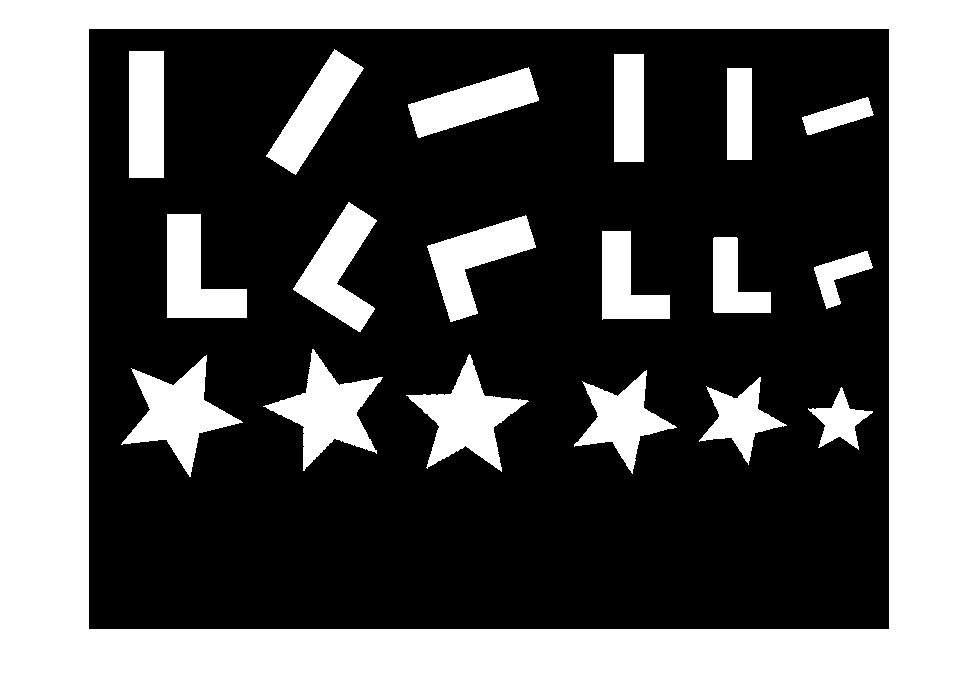

B=1-(im2bw((rgb2gray(imread("ScaleRotation1.jpg"))), 0.5));

imshow(B)

In this example we check how image segmentation using regionprops responds to shapes that are differently scaled and rotated

[label, num]=bwlabel(B);
feat=regionprops(label,"all");

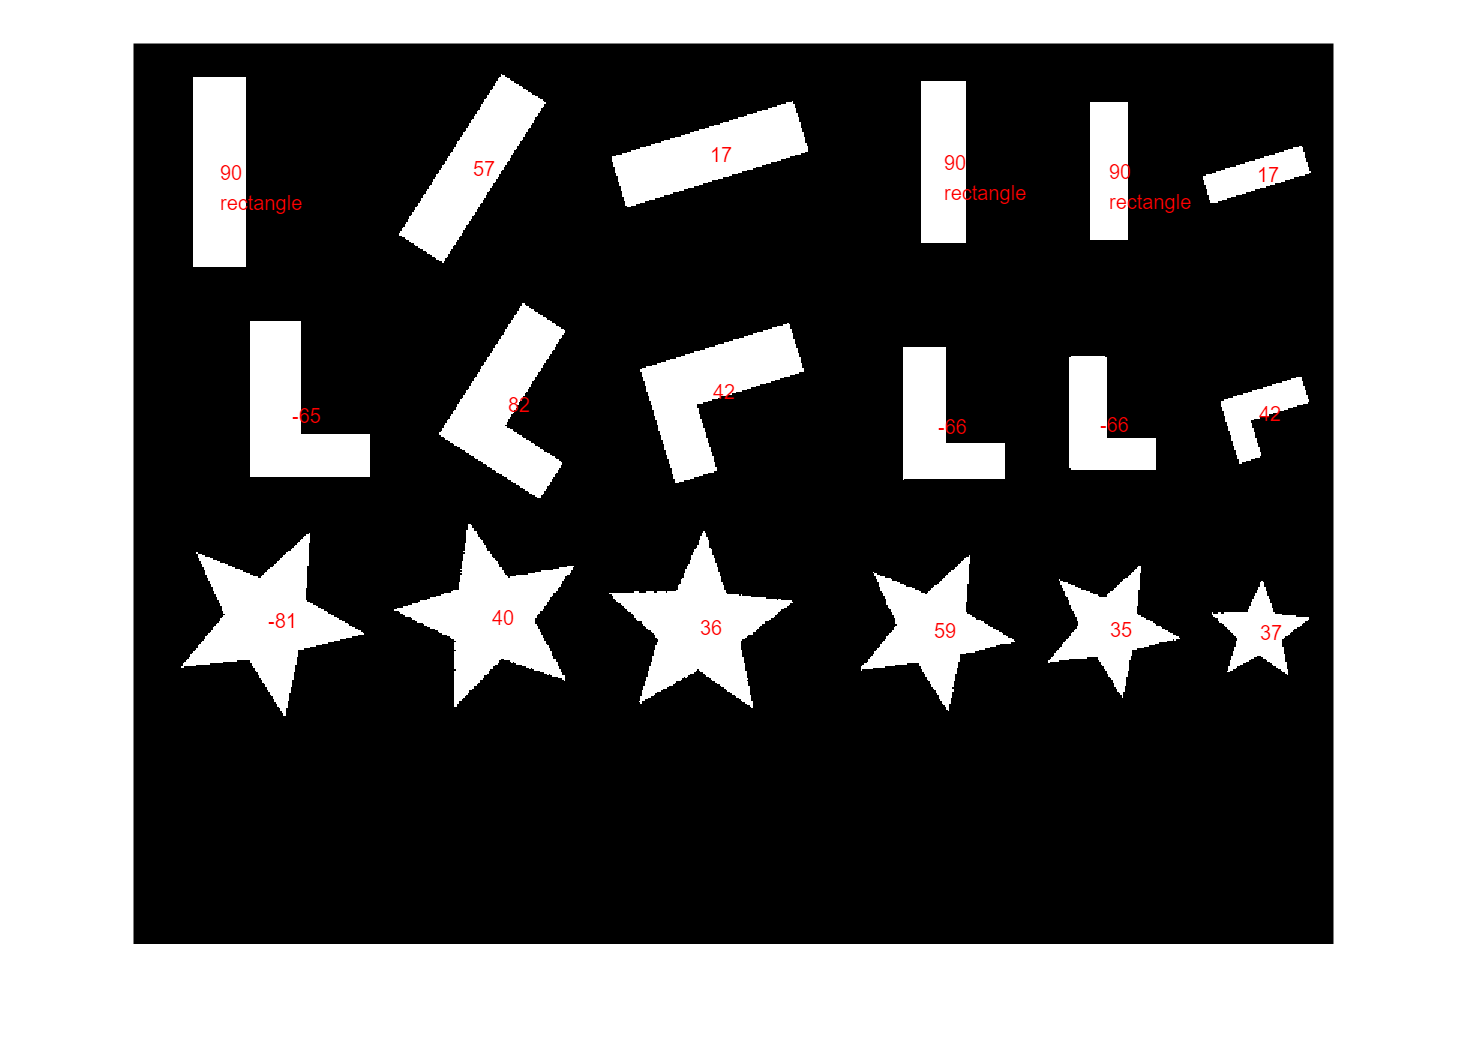


for i=1:num
    if (feat(i).BoundingBox(3)*feat(i).BoundingBox(4))==feat(i).Area
feat(i).Shape='rectangle';
text(feat(i).Centroid(1),feat(i).Centroid(2)+20,(feat(i).Shape),'Color','r')
    end
text(feat(i).Centroid(1),feat(i).Centroid(2),mat2str(round(feat(i).Orientation)),'Color','r')

    
end

We obsereve that our solution for founding rectangles only works for rectangles roteted by n*90deg. This is because the bounding box is alvays positioned straight.